# Train Hardware Soft Robot

clear vars; close all; clc;
warning('off','all')

% Number of observables
numObs = 15;
load obsDecayDataC

## Visualize Training Data

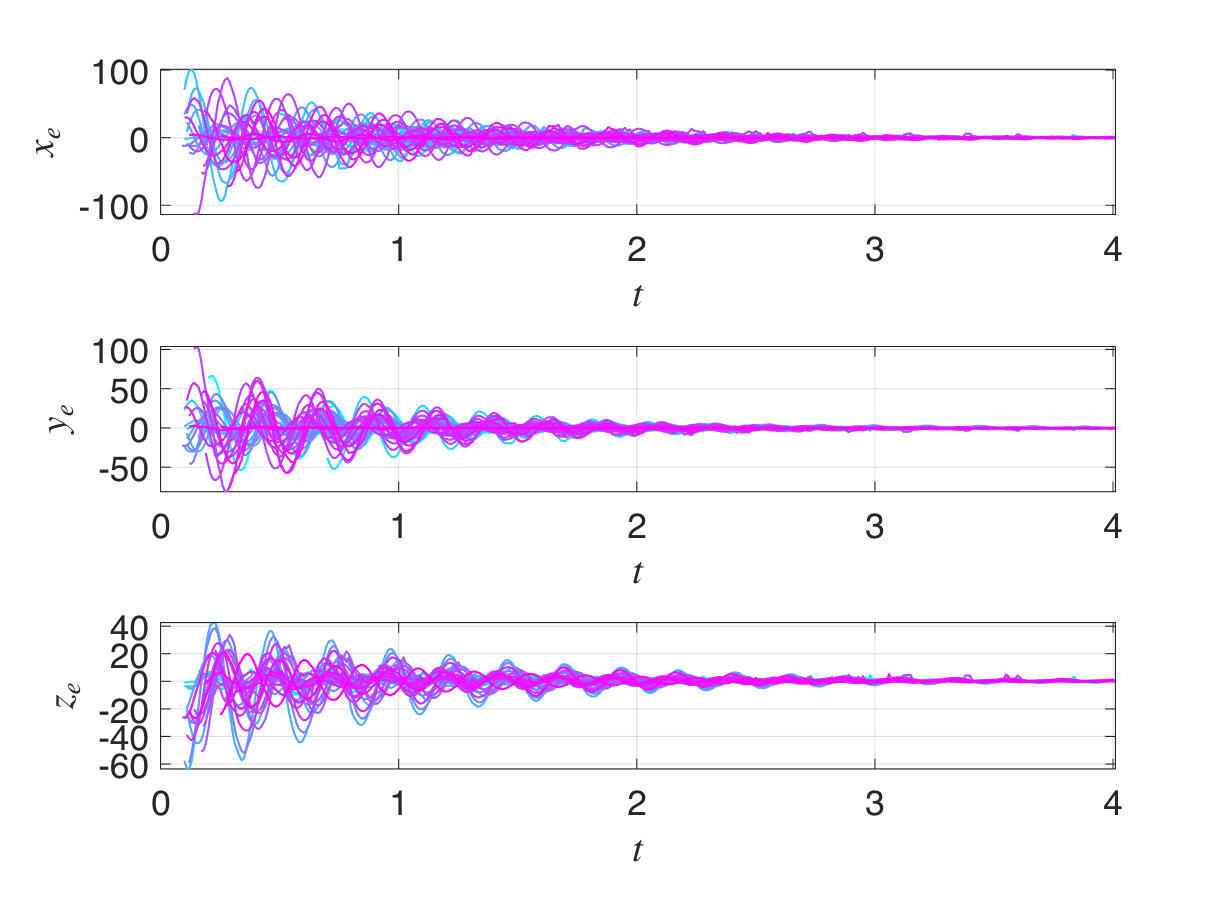

trajs = [13, 14, 15];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
    end
end

## PCA

Just to check that from positions data we get 3 dominant modes as we expect

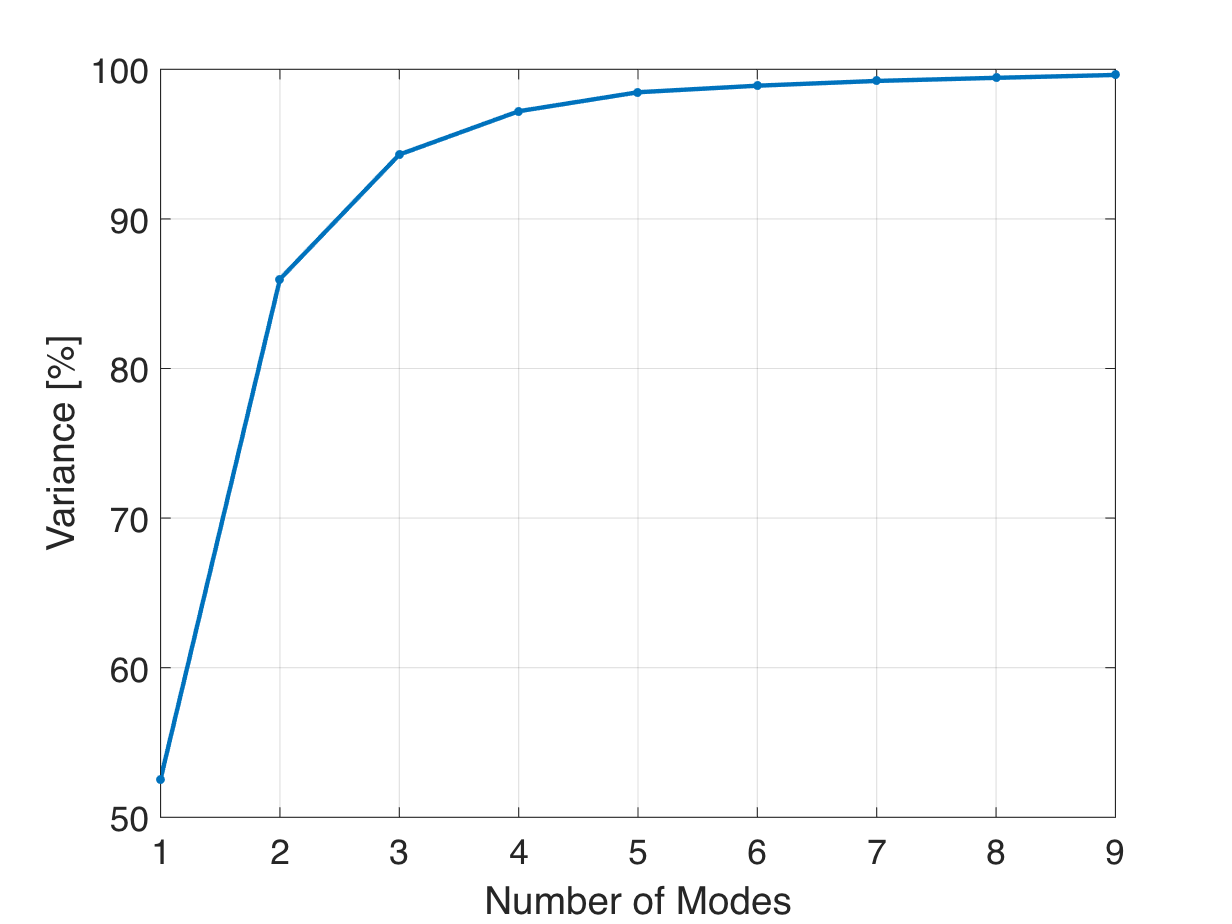

Xsnapshots = cat(2,oData{:,2});
% Perform SVD on displacement field
[V,S,~] = svd(Xsnapshots, 0);
% Plot variance description: we expect three modes to capture almost all
% variance. Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 9])
set(gca,'XTick',[1:1:9])

% Define modes
SSMDim = 6; hSSMDim = SSMDim/2;
V_PCA_space = V(:,1:hSSMDim);

Visualize PCA projections

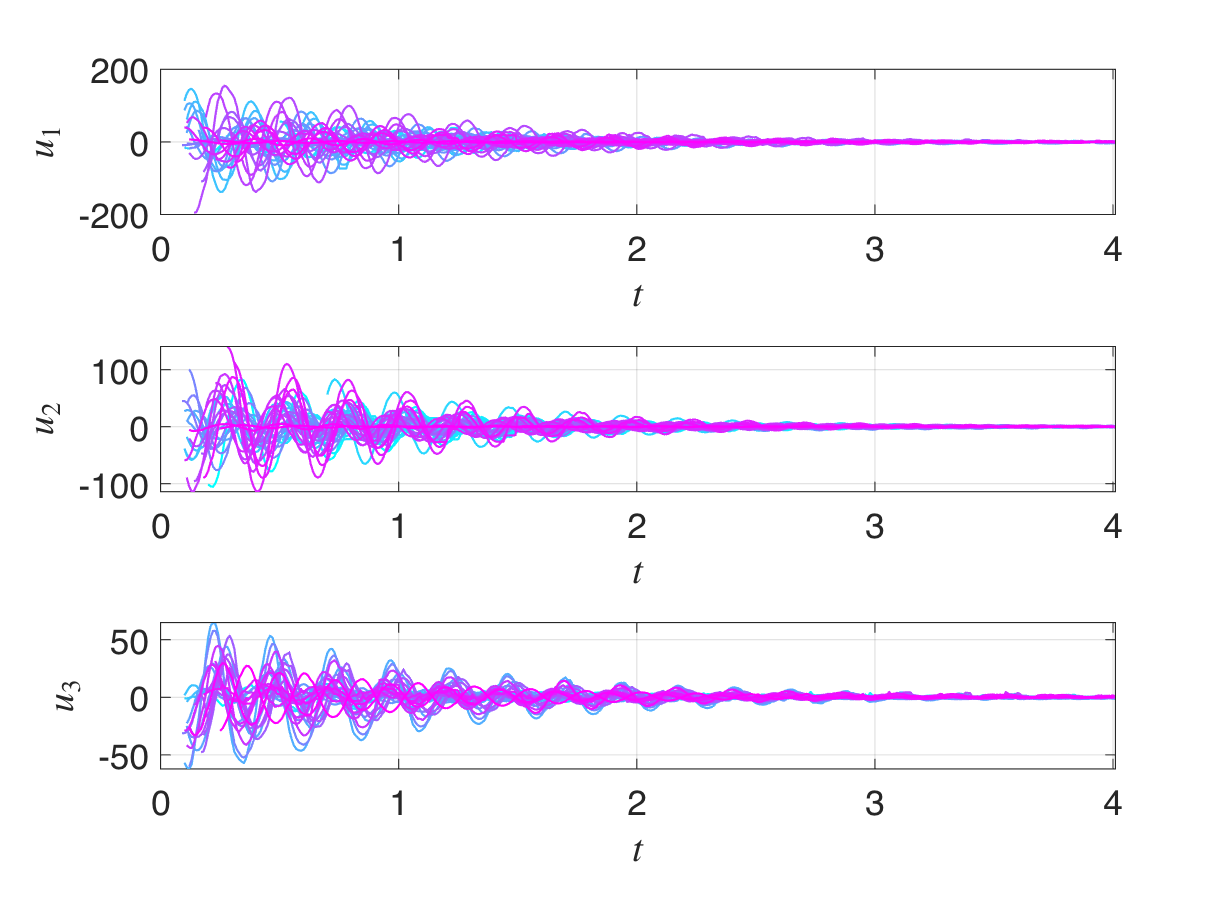

% transform trajectories
pData = oData;
customFigure('subPlot',[numCoord 1]);
labels = ["$u_1$", "$u_2$", "$u_3$"];
for iPlt = 1:hSSMDim
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    pData{iTraj,2} = transpose(V)*oData{iTraj,2};
    for iObs = 1:hSSMDim
        subplot(numCoord,1,iObs);
        plot(pData{iTraj,1},pData{iTraj,2}(iObs,:),'Linewidth',1)
    end
end

Perform delay-embedding. As observables for the model, we consider the all current positions data as well as past measurements (no future ones). We have a minimum of 0 delays, which is augmented by the `overEmbed` variable, so that the number of total delays is `overEmbed`. Delay-embedding in this case is used both for providing velocity-type data and for denoising. We also do some cutting, but it is not necessary in this case.

overEmbed = 25;
[yData, opts_embd] = coordinatesEmbeddingControl(oData, SSMDim, 'OverEmbedding', overEmbed);

The 390 embedding coordinates consist of the 15 measured states and their 25 time-delayed measurements.


embedDim = size(yData{1,2},1);
outdofs = [embedDim-2 embedDim-1 embedDim];
sliceInt = [0.01, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);


PCA is still useful in the delay-embeeded space, as the number of modes explaining most of the data should be the dimension of the SSM. Indeed, we get it as more than 90% of variance is explained by the first six PCA modes.

disp('PCA')

PCA


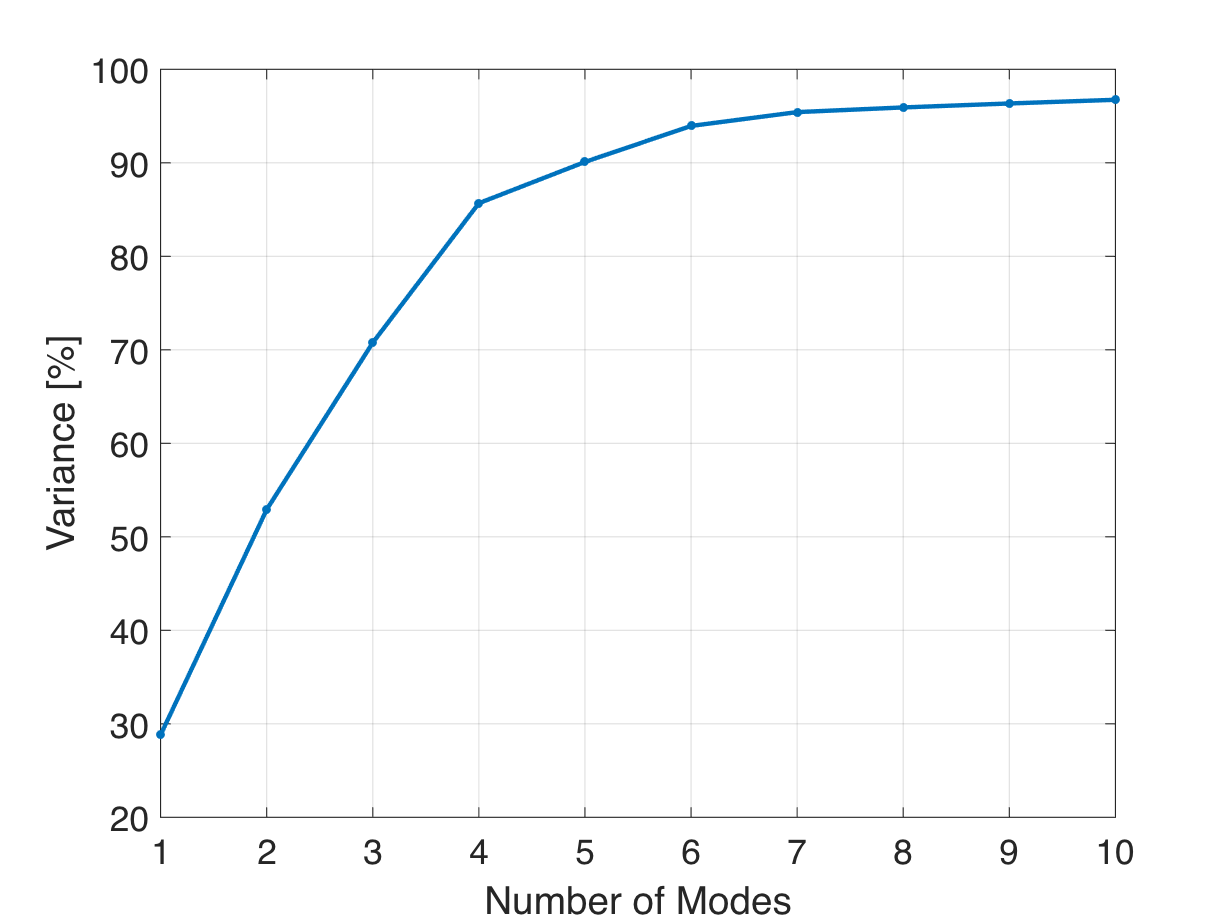

Xsnapshots = cat(2,yDataTrunc{:,2});
% Perform SVD on displacement field
[V,S,~] = svd(Xsnapshots, 0);
% Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
maxModesPlot = 10;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 maxModesPlot])
set(gca,'XTick',[1:1:maxModesPlot])


Vde = V(:,1:SSMDim);
% Set reduced-coordinates as PCA projection to the first six modes
etaDataTrunc = yDataTrunc;
for iTraj = 1:size(oData, 1)
    etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
end

% Set test and train trajectories
indTest = [5 15 21 32 38];
indTrain = setdiff(1:size(oData, 1),indTest);

## Geometry

Manifold fitting with prescribed graph. Higher orders tend to overfit.

SSMOrder = 3;
if SSMOrder == 1
    % Need to recompute as the columns of Vde might change in order
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);
    Vde = IMInfo.parametrization.tangentSpaceAtOrigin;
    etaDataTrunc = yDataTrunc;
    for iTraj = 1:size(oData, 1)
        etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
    end
else
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc(indTrain,:));
    IMInfo.chart.map = @(x) transpose(Vde)*x;
end

Evaluate learning of geometry.

disp('Results of geometry fit:')

Results of geometry fit:


yRec = liftTrajectories(IMInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 5.1977

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 4.8375

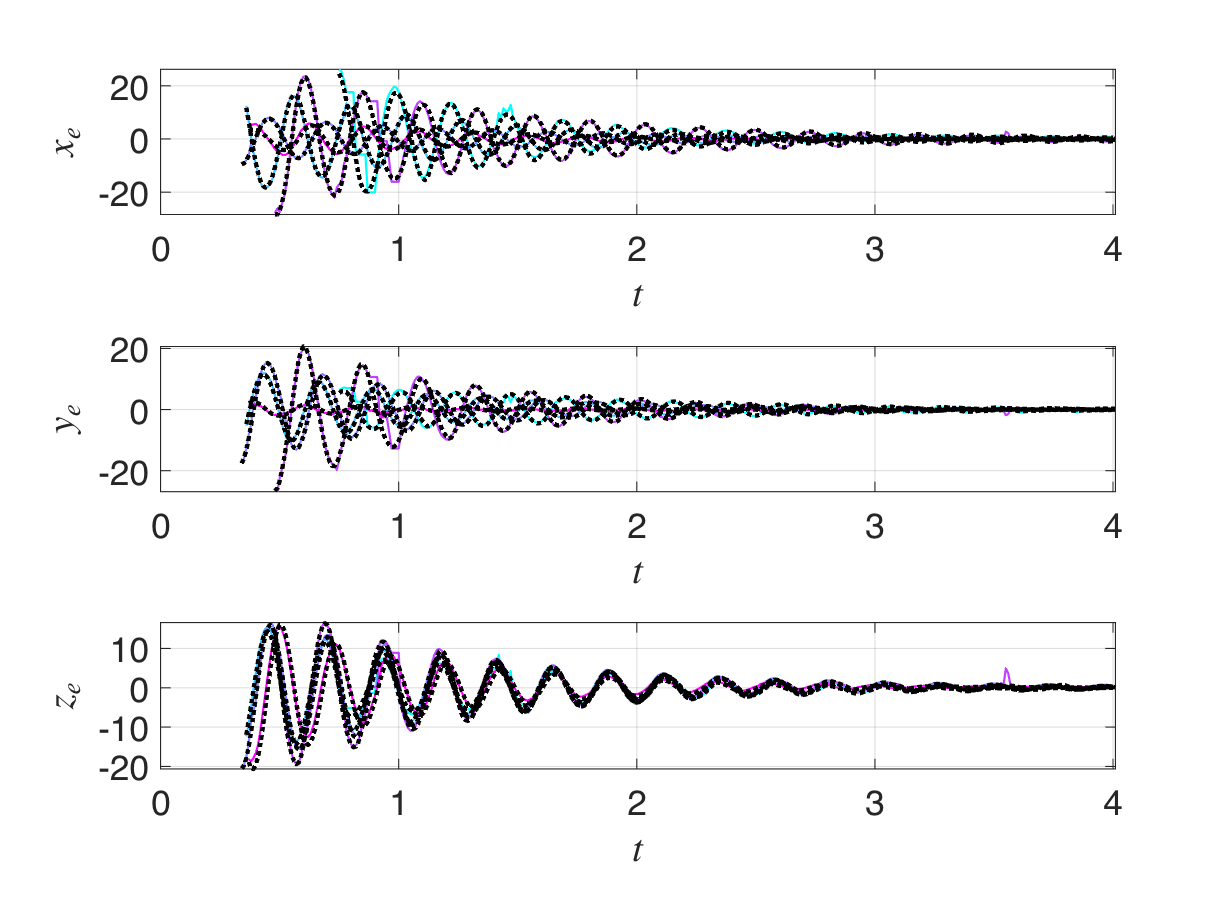


% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end

for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end

for iTraj = 1:length(indTest)
        yRec = liftTrajectories(IMInfo, etaDataTrunc(indTest(iTraj),:));
        errorGeoTest(iTraj) = computeTrajectoryErrors(yRec, yDataTrunc(indTest(iTraj),:))*100;
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{1,1},yRec{1,2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Reduced dynamics

Cubic order dynamics halves the trajectory error of linear dynamics. The `Map` case seems more accurate than the `Flow` one.

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -1.0728 +26.3872i
  -1.1633 +26.4678i
  -1.1791 +27.0399i


Evaluate learning of reduced dynamics.

disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = 8.1562

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 9.3638

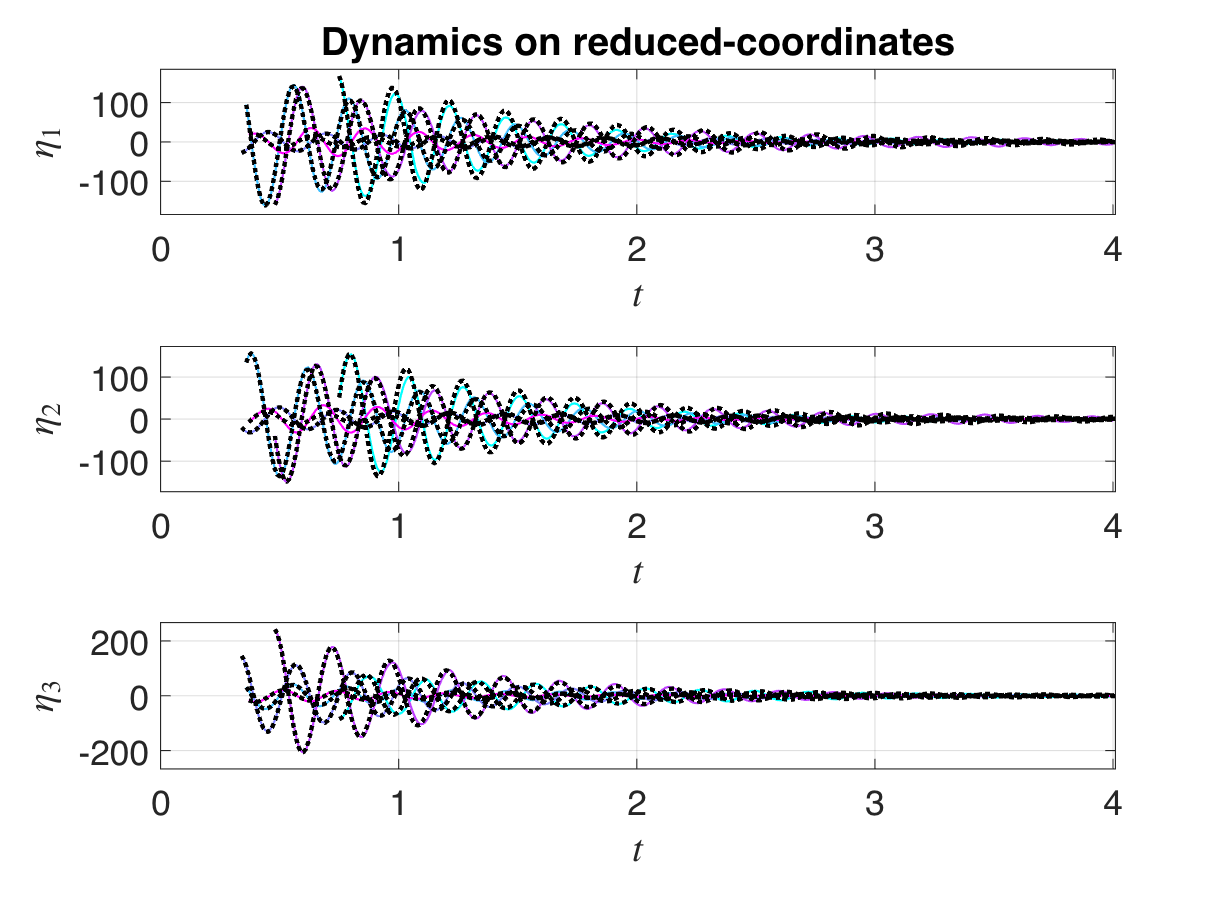


customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title('Dynamics on reduced-coordinates')
labels = ["$\eta_1$", "$\eta_2$", "$\eta_3$"];
for iPlt = 1:hSSMDim
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
yLimits = [0 0 0];
for iTraj = 1:length(indTest)
    for iObs = 1:hSSMDim
        subplot(numCoord,1,iObs);
        plot(etaDataTrunc{indTest(iTraj),1},etaDataTrunc{indTest(iTraj),2}(iObs,:),'Linewidth',1)
        yLimits(iObs) = max([max(abs(etaDataTrunc{indTest(iTraj),2}(iObs,:))) yLimits(iObs)]);
        ylim([-1 1]*1.1*yLimits(iObs))
    end
end

for iTraj = 1:length(indTest)
    for iObs = 1:hSSMDim
        subplot(numCoord,1,iObs);
        plot(etaRec{indTest(iTraj),1},etaRec{indTest(iTraj),2}(iObs,:),'k:','Linewidth',2)
    end
end

Visualize performance with real observables.

disp('Errors for the reduced-order model (geometry & dynamics):')

Errors for the reduced-order model (geometry & dynamics):


yRec = liftTrajectories(IMInfo, etaRec);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorROMTrain = mean(normedTrajDist(indTrain))*100

meanErrorROMTrain = 9.9821

meanErrorROMTest = mean(normedTrajDist(indTest))*100

meanErrorROMTest = 10.9221

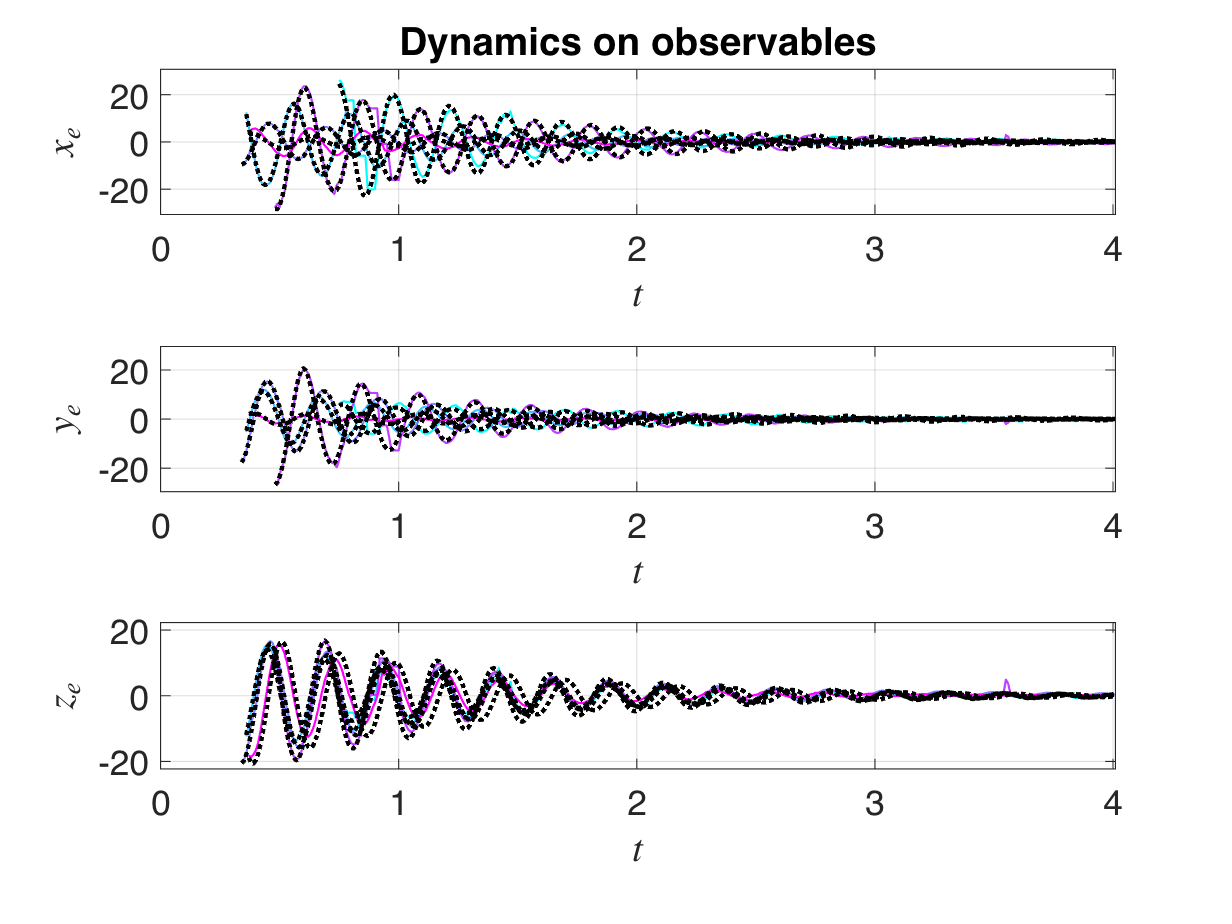


customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title('Dynamics on observables')
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
yLimits = [0 0 0];
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yDataTrunc{indTest(iTraj),1},yDataTrunc{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
        yLimits(iObs) = max([max(abs(yDataTrunc{indTest(iTraj),2}(outdofs(iObs),:))) yLimits(iObs)]);
        ylim([-1 1]*1.1*yLimits(iObs))
    end
end

for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end
hold off

Here we plot the 3 best and 3 worst predictions

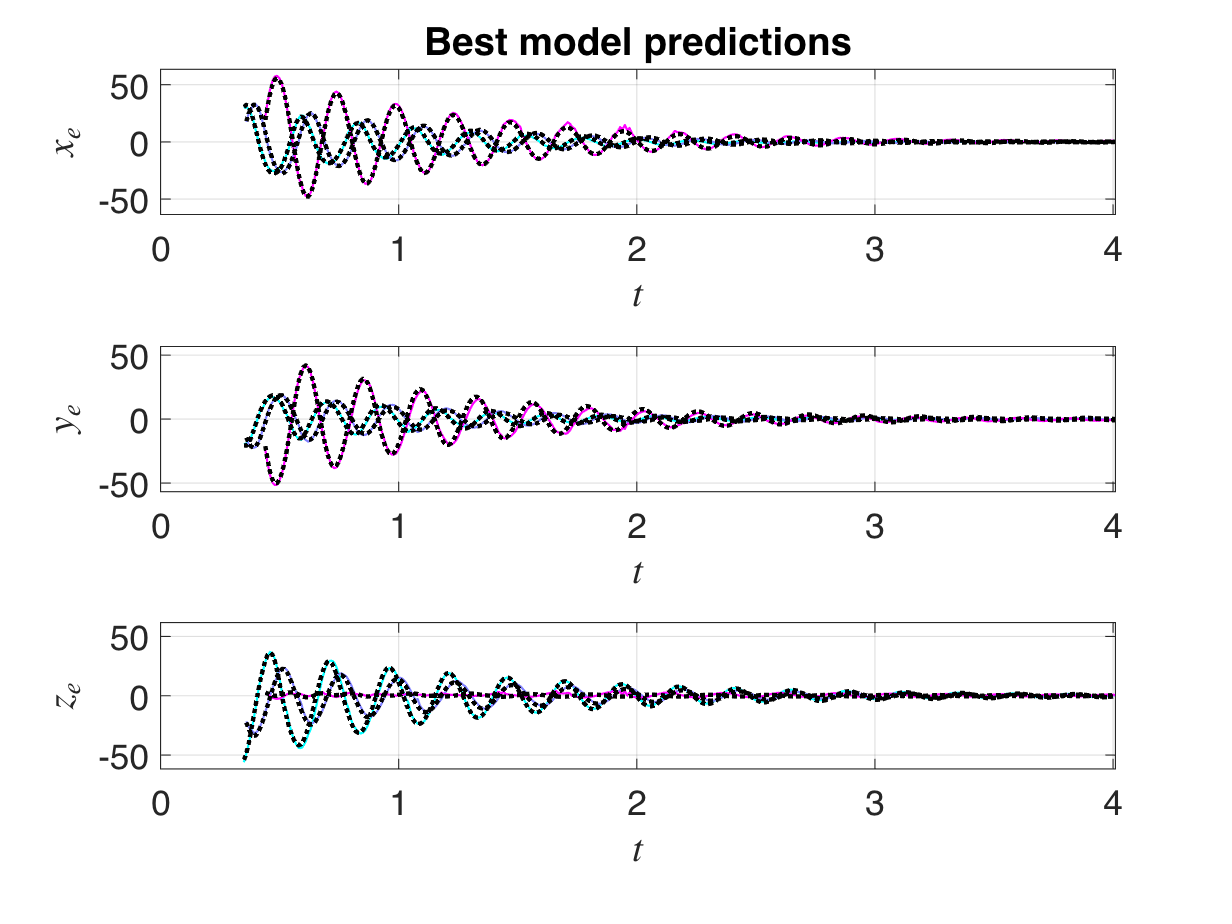

[~,ranks] = sort(normedTrajDist,'ascend');
indAct = ranks(1:3); % Best
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title('Best model predictions')
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indAct)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
yLimits = [0 0 0];
for iTraj = 1:length(indAct)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yDataTrunc{indAct(iTraj),1},yDataTrunc{indAct(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
        yLimits(iObs) = max([max(abs(yDataTrunc{indAct(iTraj),2}(outdofs(iObs),:))) yLimits(iObs)]);
        ylim([-1 1]*1.1*yLimits(iObs))
    end
end

for iTraj = 1:length(indAct)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indAct(iTraj),1},yRec{indAct(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

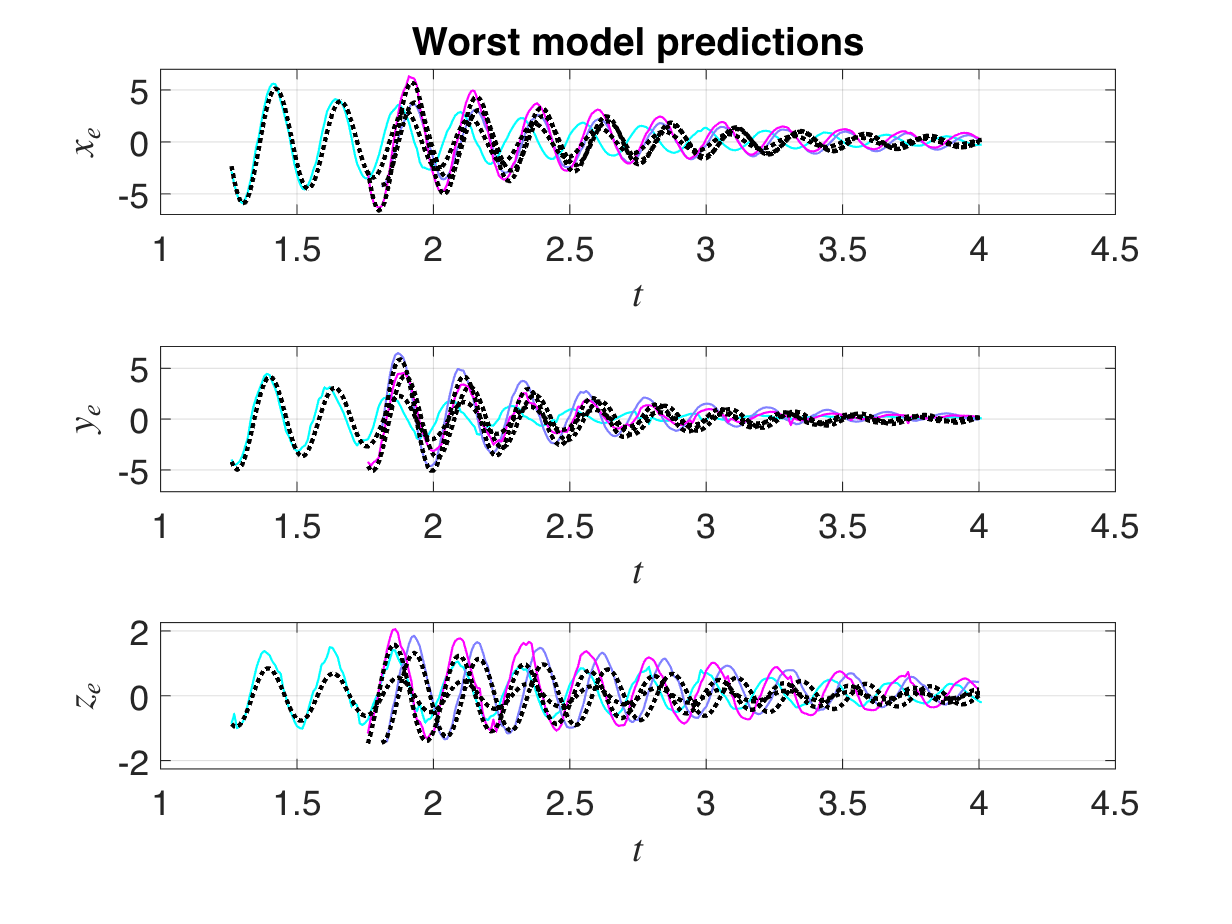


indAct = ranks(end-2:end); % Worst
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title('Worst model predictions')
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indAct)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
yLimits = [0 0 0];
for iTraj = 1:length(indAct)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yDataTrunc{indAct(iTraj),1},yDataTrunc{indAct(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
        yLimits(iObs) = max([max(abs(yDataTrunc{indAct(iTraj),2}(outdofs(iObs),:))) yLimits(iObs)]);
        ylim([-1 1]*1.1*yLimits(iObs))
    end
end

for iTraj = 1:length(indAct)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indAct(iTraj),1},yRec{indAct(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Evaluate the model performance in a control-based setting

The predictions above are done by giving the model the initial condition a given trajectory, iterate or integrate for the time-span of this trajectory and then compare the prediction with the trajectory. Hence the horizon could be of thousands or more steps. As in control we usually have way smaller horizons, here we evaluate the model performance on custom time horizons.

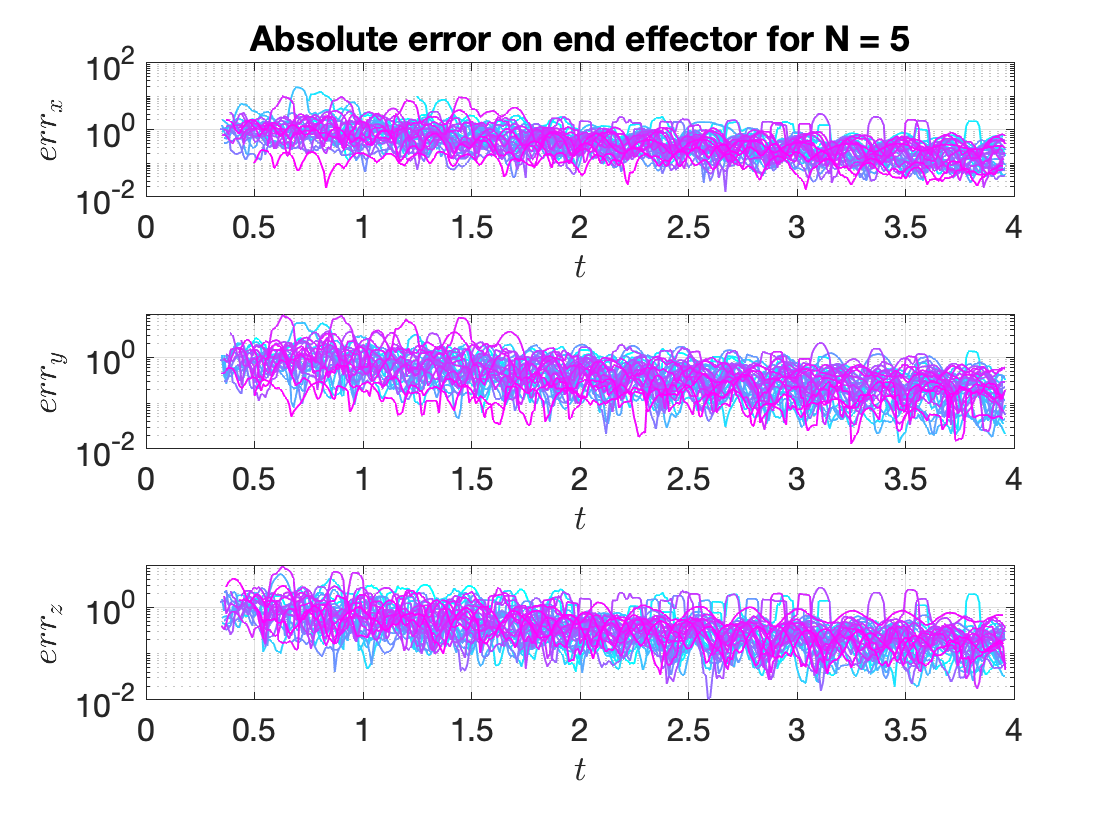

% Evaluate rolling error on the tip
Nhoriz = 5;

errData = yDataTrunc;
yDataPredHoriz = cell(1,6); iRow = 1;
for iTraj = 1:size(yDataTrunc, 1)
    itime = yDataTrunc{iTraj,1};
    nErrEval = length(itime)-Nhoriz;
    errData{iTraj,1} = errData{iTraj,1}(1:nErrEval);
    iErr = zeros(3,nErrEval);
    for iTime = 1:nErrEval
        % Integrate from proper IC for Nhoriz steps
        ietaRec = advectRD(RDInfo, {etaDataTrunc{iTraj,1}(iTime:iTime+Nhoriz), ...
                                    etaDataTrunc{iTraj,2}(:,iTime:iTime+Nhoriz)});
        % Lift
        iyRec = liftTrajectories(IMInfo, ietaRec);
        % Evaluate avg error (can be asbolute or relative, removing the
        % comment after the ;
        iErr(:,iTime) = sqrt(mean((yDataTrunc{iTraj,2}(outdofs,iTime:iTime+Nhoriz) - iyRec{1,2}(outdofs,:)).^2,2));%./max(abs(yDataTrunc{iTraj,2}(outdofs,:)),[],2)*100;%
        % Assign to cell
        yDataPredHoriz{iRow,1} = iTraj;
        yDataPredHoriz{iRow,2} = etaDataTrunc{iTraj,1}(iTime:iTime+Nhoriz);
        yDataPredHoriz{iRow,3} = iyRec{1,2}(outdofs,:);
        yDataPredHoriz{iRow,4} = etaDataTrunc{iTraj,1}(iTime+Nhoriz);
        yDataPredHoriz{iRow,5} = iTime;
        yDataPredHoriz{iRow,6} = mean(iErr(:,iTime));
        iRow = iRow + 1;
    end
    errData{iTraj,2} = iErr;
end

% Plot all errors
customFigure('subPlot',[numCoord 1]); 
subplot(numCoord,1,1); title(['Absolute error on end effector for N = ' num2str(Nhoriz)])
labels = ["$err_x$", "$err_y$", "$err_z$"];
for iPlt = 1:hSSMDim
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:hSSMDim
        subplot(numCoord,1,iObs);
        plot(errData{iTraj,1},errData{iTraj,2}(iObs,:),'Linewidth',1)
        set(gca,'yscale','log')
    end
end

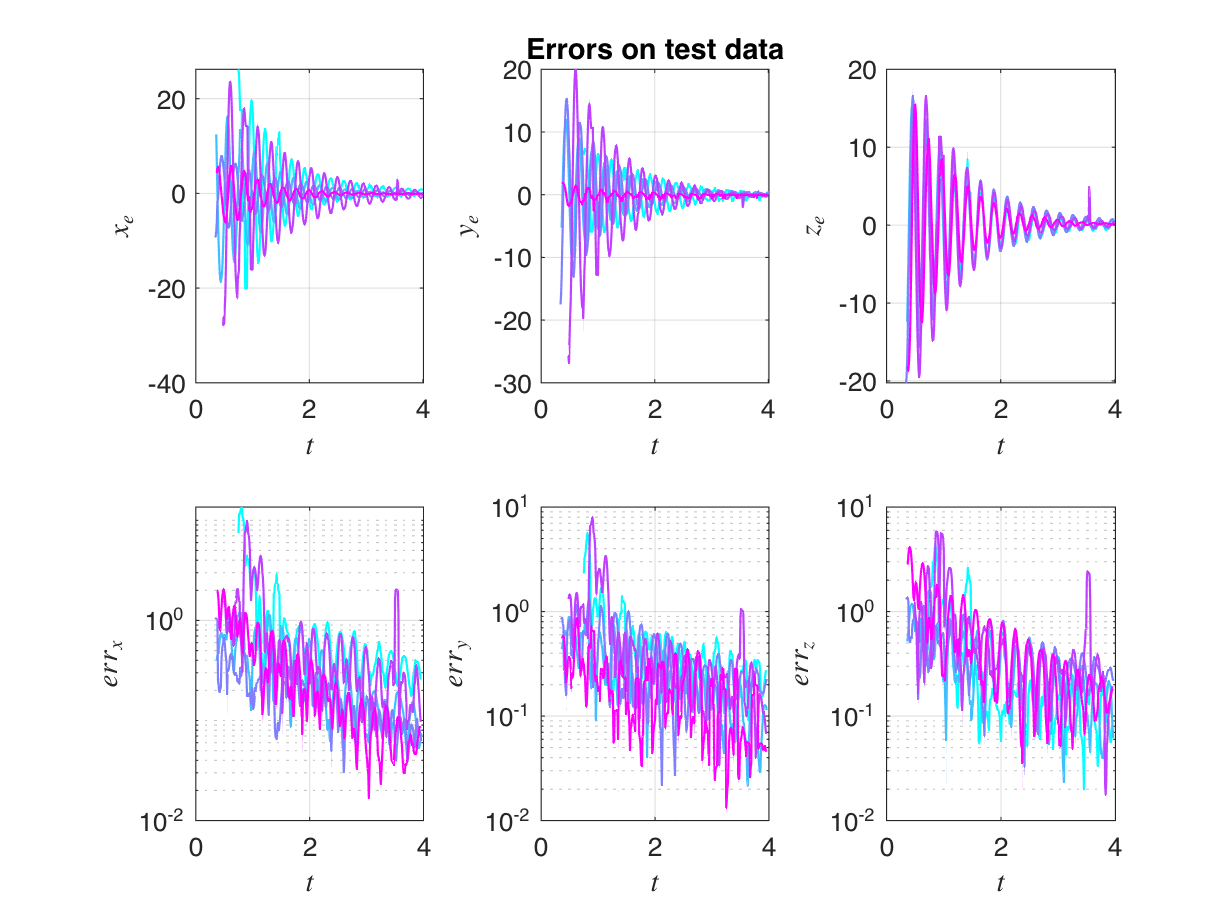


% Plot errors with test trajectories 
customFigure('subPlot',[2 numCoord]); 
subplot(2,numCoord,2); title('Errors on test data') 
labelsUp = ["$x_e$", "$y_e$", "$z_e$"];
labelsDown = ["$err_x$", "$err_y$", "$err_z$"];
for iPlt = 1:hSSMDim
    subplot(2,numCoord,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labelsUp(iPlt),'Interpreter','latex');
end
for iPlt = 1:hSSMDim
    subplot(2,numCoord,iPlt+3); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labelsDown(iPlt),'Interpreter','latex');
end

for iTraj = 1:length(indTest)
    for iObs = 1:hSSMDim
        subplot(2,numCoord,iObs);
        plot(yDataTrunc{indTest(iTraj),1},yDataTrunc{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end

for iTraj = 1:length(indTest)
    for iObs = 1:hSSMDim
        subplot(2,numCoord,iObs+3);
        plot(errData{indTest(iTraj),1},errData{indTest(iTraj),2}(iObs,:),'Linewidth',1)
        set(gca,'yscale','log')
    end
end

We now visualize the best and worst predictions of trajectory segments.

% Extract errors on each segment
segErrors = cat(2,yDataPredHoriz{:,end});
% We can prescribe for example, to consider samples whose max time is less
% than tMax
tMax = 1;
timeSegErrors = cat(2,yDataPredHoriz{:,4});
segErrors(timeSegErrors>tMax) = NaN; nNaN = sum(isnan(segErrors));
% Number of trajectories to plot
nTrajs = 5;
% Get ranks
[~,ranks] = sort(segErrors,'ascend');

disp(['Best ' num2str(nTrajs) ' segment predictions, with errors: ' num2str(segErrors(ranks(1:nTrajs)))])

Best 5 segment predictions, with errors: 0.12234     0.12283     0.14246     0.15651     0.16851


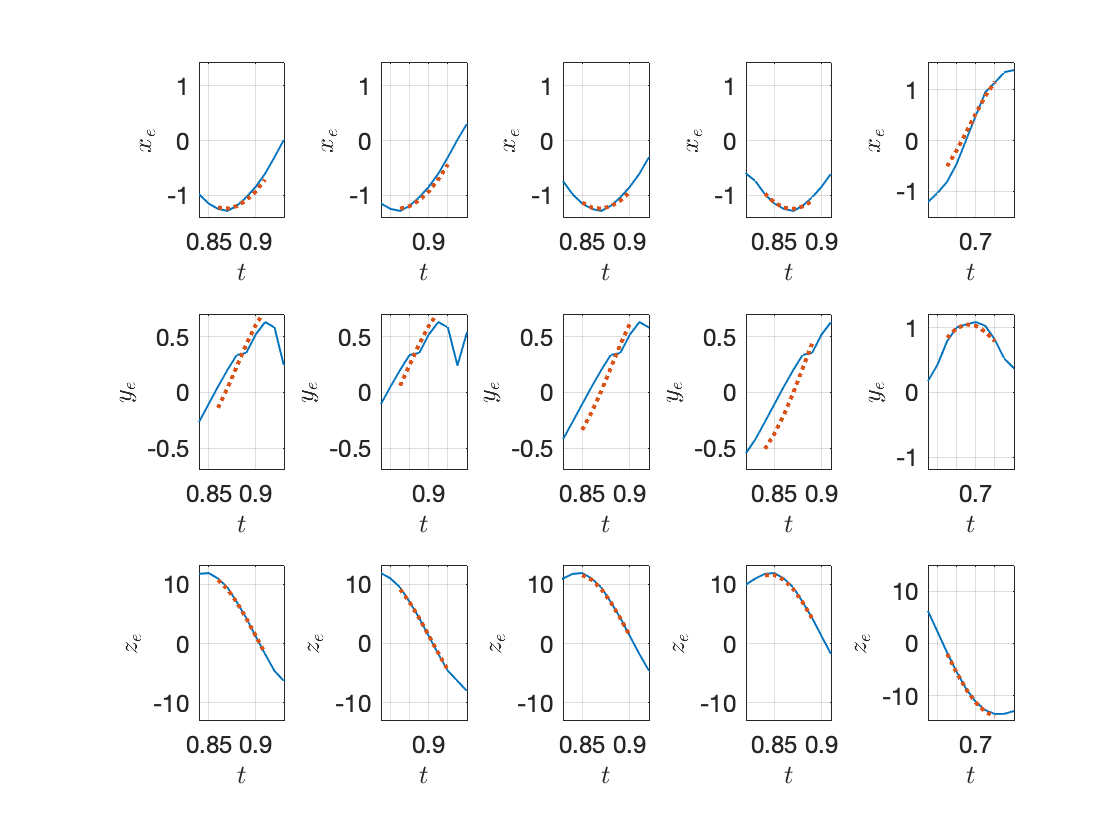

indAct = [yDataPredHoriz{ranks(1:nTrajs),1}]; % Best
customFigure('subPlot',[numCoord nTrajs]);
subplot(numCoord,nTrajs,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iRow = 1:length(outdofs)
for iCol = 1:nTrajs
    subplot(numCoord,nTrajs,iCol+(iRow-1)*nTrajs); %colororder(cool(length(indAct)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iRow),'Interpreter','latex');
end
end
ntBorders = floor(Nhoriz/2);
for iCol = 1:length(indAct)
    tPred = yDataPredHoriz{ranks(iCol),2}; Dt = tPred(2)-tPred(1);
    yPred = yDataPredHoriz{ranks(iCol),3}; iTime = yDataPredHoriz{ranks(iCol),5};
    for iRow = 1:length(outdofs)
        subplot(numCoord,nTrajs,iCol+(iRow-1)*nTrajs);
        plot(yDataTrunc{indAct(iCol),1},yDataTrunc{indAct(iCol),2}(outdofs(iRow),:),'Linewidth',1)
        plot(tPred,yPred(iRow,:),':','Linewidth',2)
        xlim([tPred(1)-ntBorders*Dt tPred(end)+ntBorders*Dt])
        indIni = iTime; if iTime>ntBorders; indIni = iTime-ntBorders; end
        indEnd = iTime+Nhoriz+ntBorders; if size(yDataTrunc{indAct(iCol),2},2)<indEnd; indEnd = iTime+Nhoriz; end
        ylim([-1 1]*1.1*max(abs(yDataTrunc{indAct(iCol),2}(outdofs(iRow),indIni:indEnd))))
    end
end


disp(['Worst ' num2str(nTrajs) ' segment predictions, with errors: ' num2str(segErrors(ranks(end-nTrajs+1-nNaN:end-nNaN)))])

Worst 5 segment predictions, with errors: 7.9822      8.3364      8.4956      8.5187      8.7324


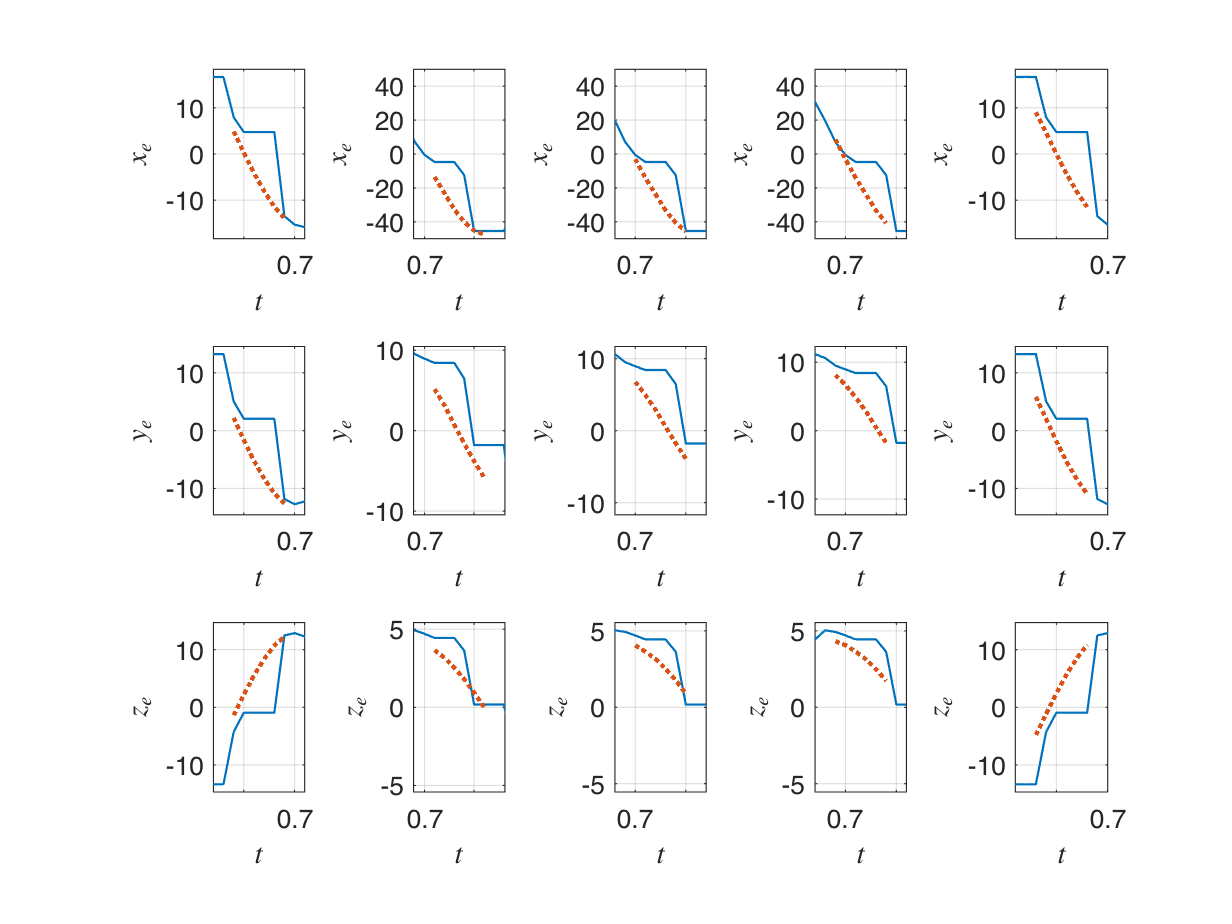

indAct = [yDataPredHoriz{ranks(end-nTrajs+1-nNaN:end-nNaN),1}]; % Worst
customFigure('subPlot',[numCoord nTrajs]);
subplot(numCoord,nTrajs,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iRow = 1:length(outdofs)
for iCol = 1:nTrajs
    subplot(numCoord,nTrajs,iCol+(iRow-1)*nTrajs); %colororder(cool(length(indAct)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iRow),'Interpreter','latex');
end
end
ntBorders = floor(Nhoriz/2);
for iCol = 1:length(indAct)
    tPred = yDataPredHoriz{ranks(end-nTrajs+iCol-nNaN),2}; Dt = tPred(2)-tPred(1);
    yPred = yDataPredHoriz{ranks(end-nTrajs+iCol-nNaN),3}; iTime = yDataPredHoriz{ranks(end-nTrajs+iCol-nNaN),5};
    for iRow = 1:length(outdofs)
        subplot(numCoord,nTrajs,iCol+(iRow-1)*nTrajs);
        plot(yDataTrunc{indAct(iCol),1},yDataTrunc{indAct(iCol),2}(outdofs(iRow),:),'Linewidth',1)
        plot(tPred,yPred(iRow,:),':','Linewidth',2)
        xlim([tPred(1)-ntBorders*Dt tPred(end)+ntBorders*Dt])
        indIni = iTime; if iTime>ntBorders; indIni = iTime-ntBorders; end
        indEnd = iTime+Nhoriz+ntBorders; if size(yDataTrunc{indAct(iCol),2},2)<indEnd; indEnd = iTime+Nhoriz; end
        ylim([-1 1]*1.1*max(abs(yDataTrunc{indAct(iCol),2}(outdofs(iRow),indIni:indEnd))))
    end
end

We now do the same as above, but focusing on the reduced dynamics only.

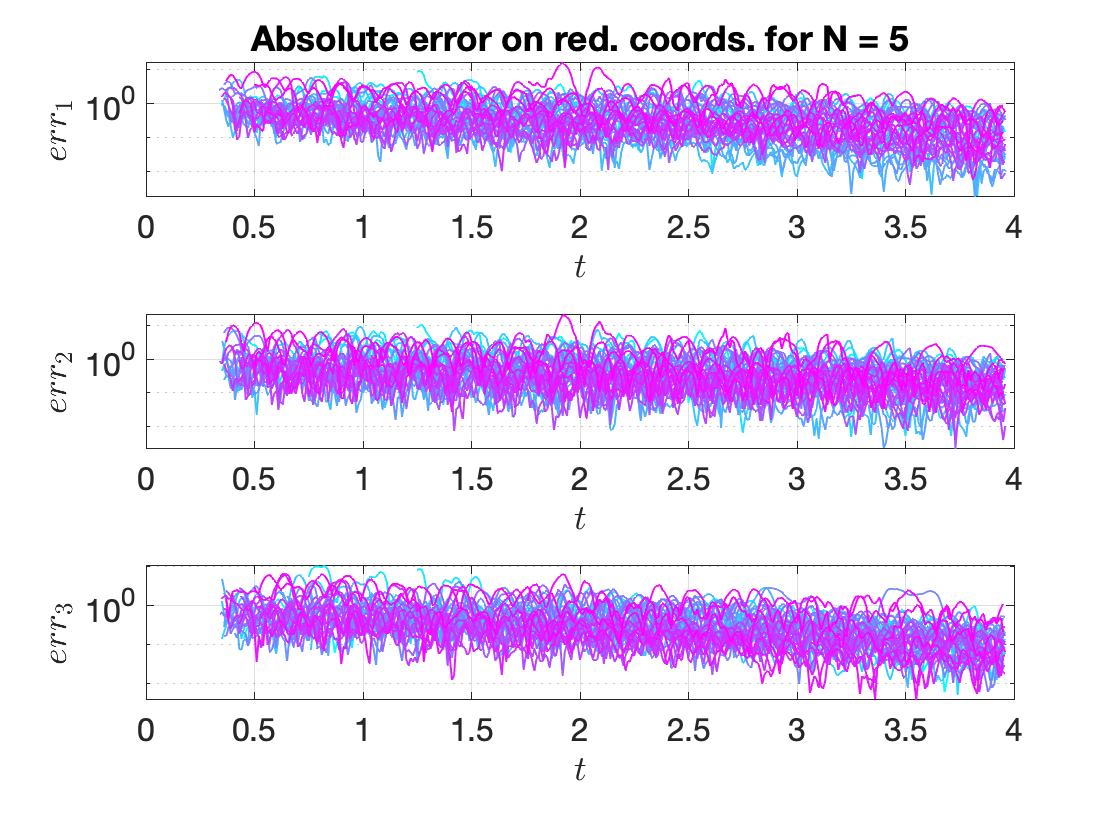

Nhoriz = 5;

errData = yDataTrunc;
etaDataPredHoriz = cell(1,6); iRow = 1; aa = 0;
for iTraj = 1:size(yDataTrunc, 1)
    itime = etaDataTrunc{iTraj,1};
    nErrEval = length(itime)-Nhoriz;
    errData{iTraj,1} = errData{iTraj,1}(1:nErrEval);
    iErr = zeros(6,nErrEval);
    for iTime = 1:nErrEval
        % Integrate from proper IC for Nhoriz steps
        ietaRec = advectRD(RDInfo, {etaDataTrunc{iTraj,1}(iTime:iTime+Nhoriz), ...
                                    etaDataTrunc{iTraj,2}(:,iTime:iTime+Nhoriz)});
        % Lift
        % Evaluate avg error
        iErr(:,iTime) = sqrt(mean((etaDataTrunc{iTraj,2}(:,iTime:iTime+Nhoriz) - ietaRec{1,2}(:,:)).^2,2))./max(abs(etaDataTrunc{iTraj,2}),[],2)*100;%;%
        % Assign to cell
        yDataPredHoriz{iRow,1} = iTraj;
        yDataPredHoriz{iRow,2} = etaDataTrunc{iTraj,1}(iTime:iTime+Nhoriz);
        yDataPredHoriz{iRow,3} = ietaRec{1,2}(:,:);
        yDataPredHoriz{iRow,4} = etaDataTrunc{iTraj,1}(iTime+Nhoriz);
        yDataPredHoriz{iRow,5} = iTime;
        yDataPredHoriz{iRow,6} = mean(iErr(:,iTime));
        iRow = iRow + 1;
        aa = aa + norm(ietaRec{1,2}(:,1)-etaDataTrunc{iTraj,2}(:,iTime));
    end
    errData{iTraj,2} = iErr;
end


customFigure('subPlot',[numCoord 1]); 
subplot(numCoord,1,1); title(['Absolute error on red. coords. for N = ' num2str(Nhoriz)])
labels = ["$err_1$", "$err_2$", "$err_3$"];
for iPlt = 1:hSSMDim
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
%     if iPlt == 1; title(['Absolute error on end effector for N = ' num2str(Nhoriz)]); end
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:hSSMDim
        subplot(numCoord,1,iObs);
        plot(errData{iTraj,1},errData{iTraj,2}(iObs,:),'Linewidth',1)
        set(gca,'yscale','log')
    end
end

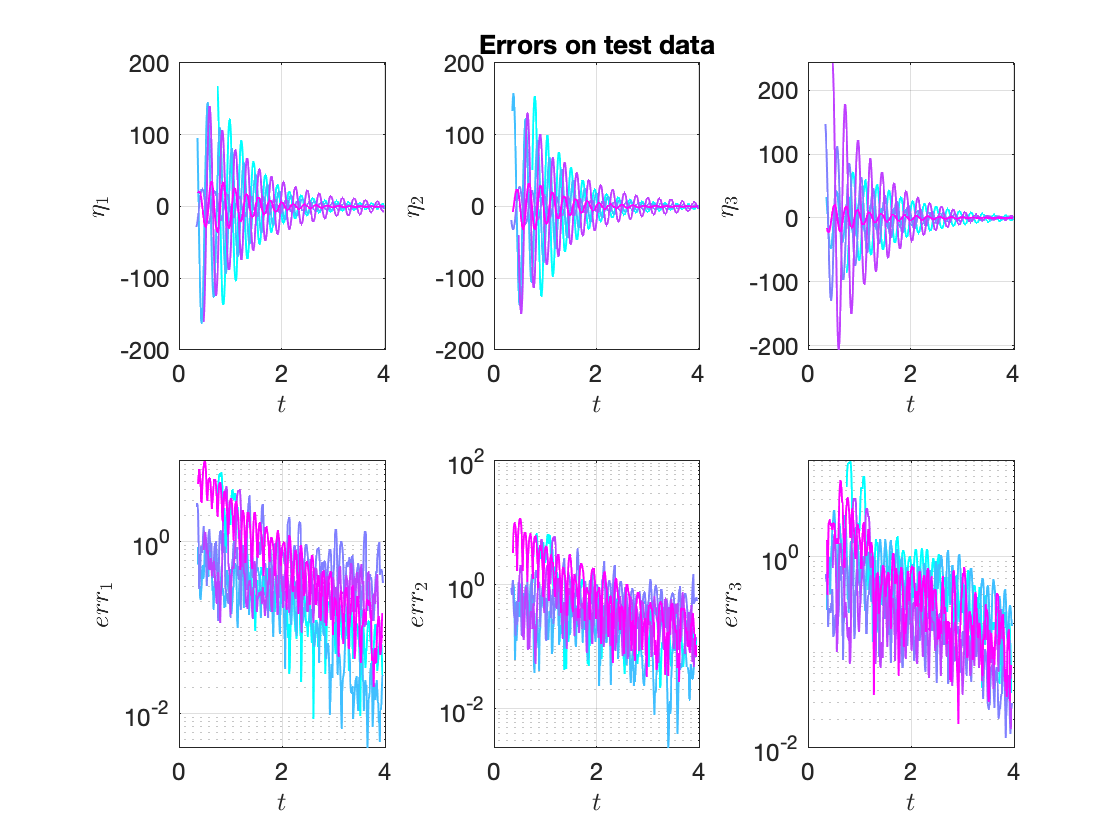


customFigure('subPlot',[2 numCoord]); 
subplot(2,numCoord,2); title('Errors on test data') 
labelsUp = ["$\eta_1$", "$\eta_2$", "$\eta_3$"];
labelsDown = ["$err_1$", "$err_2$", "$err_3$"];
for iPlt = 1:hSSMDim
    subplot(2,numCoord,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labelsUp(iPlt),'Interpreter','latex');
end
for iPlt = 1:hSSMDim
    subplot(2,numCoord,iPlt+3); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labelsDown(iPlt),'Interpreter','latex');
end

for iTraj = 1:length(indTest)
    for iObs = 1:hSSMDim
        subplot(2,numCoord,iObs);
        plot(etaDataTrunc{indTest(iTraj),1},etaDataTrunc{indTest(iTraj),2}(iObs,:),'Linewidth',1)
    end
end

for iTraj = 1:length(indTest)
    for iObs = 1:hSSMDim
        subplot(2,numCoord,iObs+3);
        plot(errData{indTest(iTraj),1},errData{indTest(iTraj),2}(iObs,:),'Linewidth',1)
        set(gca,'yscale','log')
    end
end

We now visualize the best and worst predictions of trajectory segments.

% Extract errors on each segment
segErrors = cat(2,yDataPredHoriz{:,end});
% We can prescribe for example, to consider samples whose max time is less
% than tMax
tMax = 1;
timeSegErrors = cat(2,yDataPredHoriz{:,4});
segErrors(timeSegErrors>tMax) = NaN; nNaN = sum(isnan(segErrors));
% Number of trajectories to plot
nTrajs = 5;
% Get ranks
[~,ranks] = sort(segErrors,'ascend');

disp(['Best ' num2str(nTrajs) ' segment predictions, with errors: ' num2str(segErrors(ranks(1:nTrajs)))])

Best 5 segment predictions, with errors: 0.1242     0.15071     0.15248     0.16947     0.16981


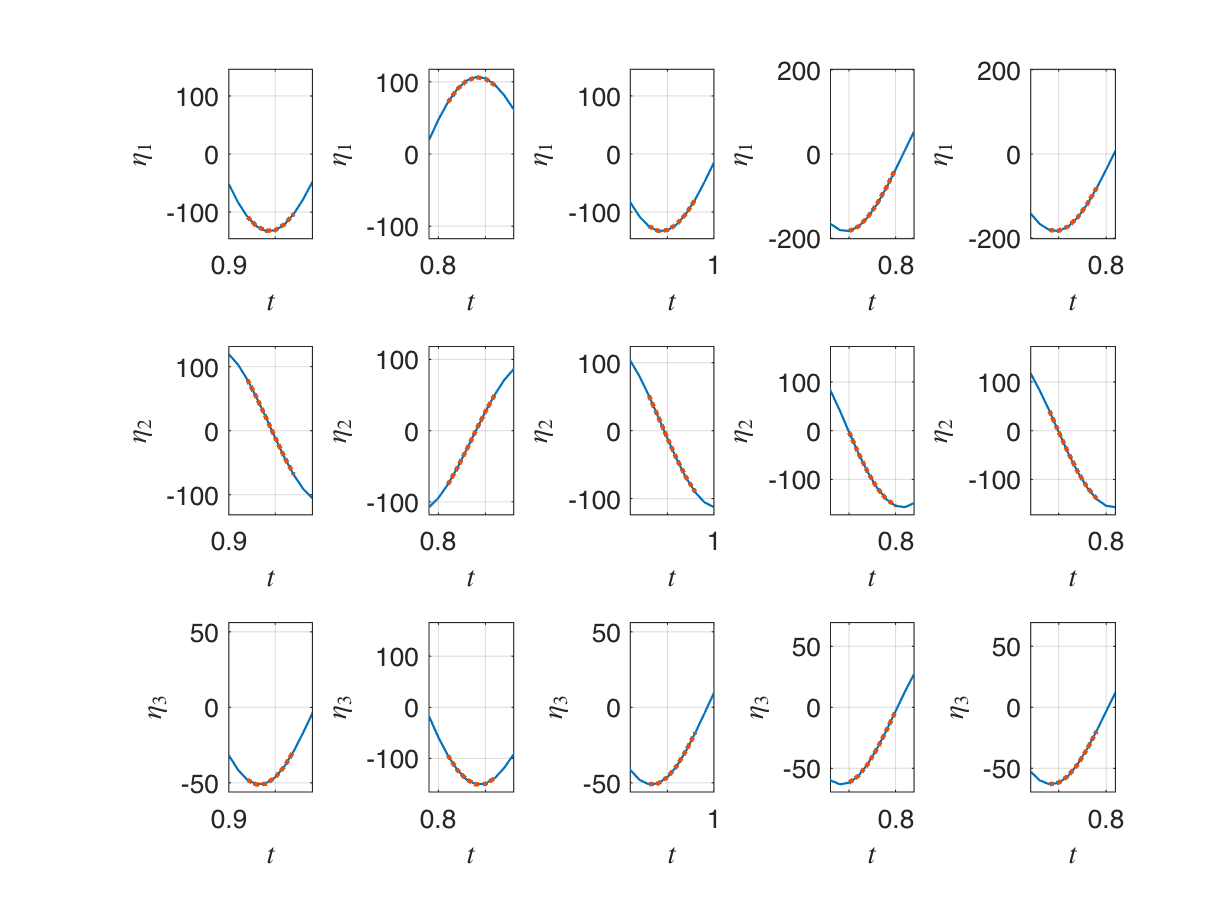

indAct = [yDataPredHoriz{ranks(1:nTrajs),1}]; % Best
customFigure('subPlot',[numCoord nTrajs]);
subplot(numCoord,nTrajs,1);
labels = ["$\eta_1$", "$\eta_2$", "$\eta_3$"];
for iRow = 1:length(outdofs)
for iCol = 1:nTrajs
    subplot(numCoord,nTrajs,iCol+(iRow-1)*nTrajs); %colororder(cool(length(indAct)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iRow),'Interpreter','latex');
end
end

ntBorders = floor(Nhoriz/2);
for iCol = 1:length(indAct) 
    tPred = yDataPredHoriz{ranks(iCol),2}; Dt = tPred(2)-tPred(1);
    etaPred = yDataPredHoriz{ranks(iCol),3}; iTime = yDataPredHoriz{ranks(iCol),5};
    for iRow = 1:length(outdofs)
        subplot(numCoord,nTrajs,iCol+(iRow-1)*nTrajs);
        plot(etaDataTrunc{indAct(iCol),1},etaDataTrunc{indAct(iCol),2}(iRow,:),'Linewidth',1)
        plot(tPred,etaPred(iRow,:),':','Linewidth',2)
        xlim([tPred(1)-ntBorders*Dt tPred(end)+ntBorders*Dt])
        indIni = iTime; if iTime>ntBorders; indIni = iTime-ntBorders; end
        indEnd = iTime+Nhoriz+ntBorders; if size(etaDataTrunc{indAct(iCol),2},2)<indEnd; indEnd = iTime+Nhoriz; end
        ylim([-1 1]*1.1*max(abs(etaDataTrunc{indAct(iCol),2}(iRow,indIni:indEnd))))
    end
end


disp(['Worst ' num2str(nTrajs) ' segment predictions, with errors: ' num2str(segErrors(ranks(end-nTrajs+1-nNaN:end-nNaN)))])

Worst 5 segment predictions, with errors: 6.4029      6.6028      6.6068      6.8075      7.3021


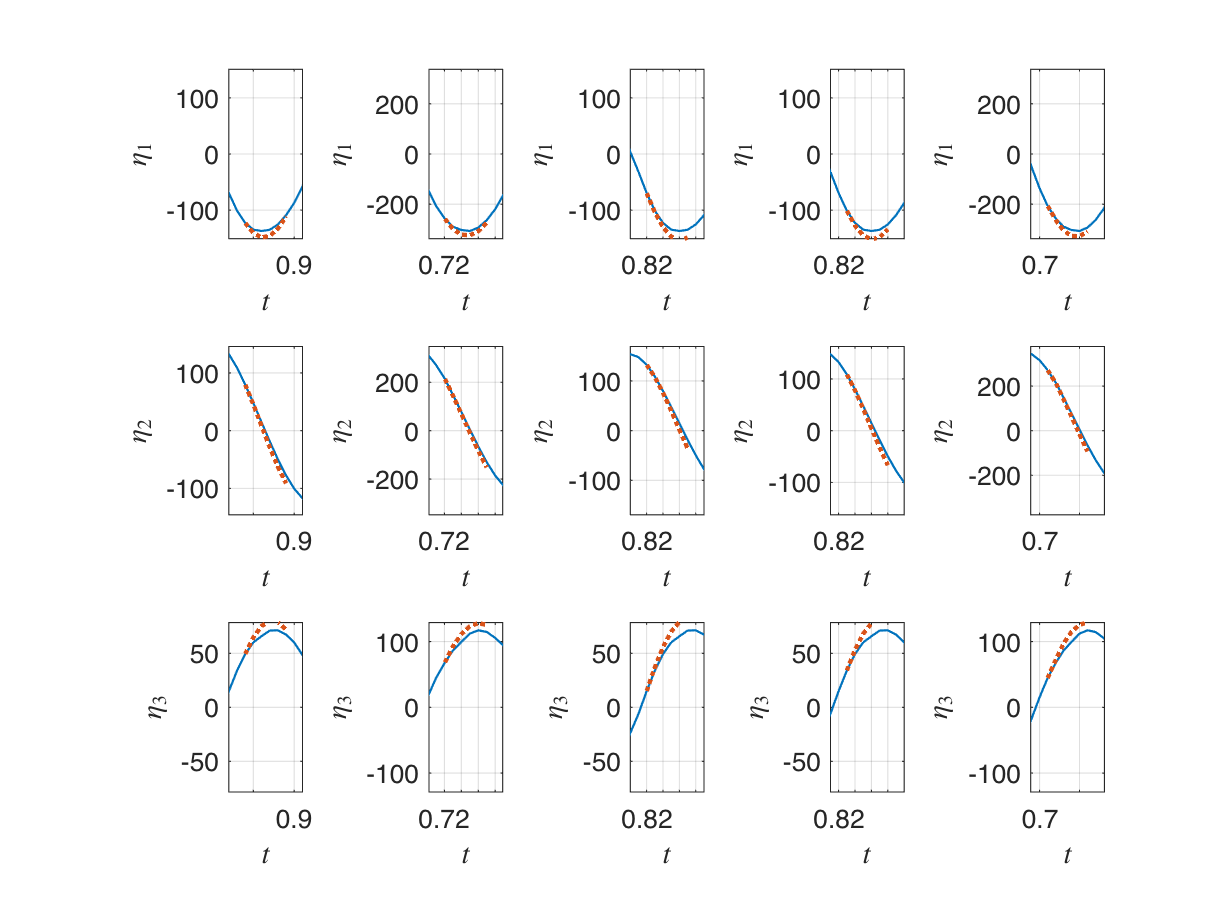

indAct = [yDataPredHoriz{ranks(end-nTrajs+1-nNaN:end-nNaN),1}]; % Worst
customFigure('subPlot',[numCoord nTrajs]);
subplot(numCoord,nTrajs,1);
labels = ["$\eta_1$", "$\eta_2$", "$\eta_3$"];
for iRow = 1:length(outdofs)
for iCol = 1:nTrajs
    subplot(numCoord,nTrajs,iCol+(iRow-1)*nTrajs); %colororder(cool(length(indAct)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iRow),'Interpreter','latex');
end
end
for iCol = 1:length(indAct)
    tPred = yDataPredHoriz{ranks(end-nTrajs+iCol-nNaN),2}; Dt = tPred(2)-tPred(1);
    etaPred = yDataPredHoriz{ranks(end-nTrajs+iCol-nNaN),3}; iTime = yDataPredHoriz{ranks(end-nTrajs+iCol-nNaN),5};
    for iRow = 1:length(outdofs)
        subplot(numCoord,nTrajs,iCol+(iRow-1)*nTrajs);
        plot(etaDataTrunc{indAct(iCol),1},etaDataTrunc{indAct(iCol),2}(iRow,:),'Linewidth',1)
        plot(tPred,etaPred(iRow,:),':','Linewidth',2)
        xlim([tPred(1)-ntBorders*Dt tPred(end)+ntBorders*Dt])
        indIni = iTime; if iTime>ntBorders; indIni = iTime-ntBorders; end
        indEnd = iTime+Nhoriz+ntBorders; if size(etaDataTrunc{indAct(iCol),2},2)<indEnd; indEnd = iTime+Nhoriz; end
        ylim([-1 1]*1.1*max(abs(etaDataTrunc{indAct(iCol),2}(iRow,indIni:indEnd))))
    end
end